# Sync the data between IMU and MC system

## Purpose of file

- Sync the time between the IMU measurements and the MC measurements, that is, estimate the time-shift. 

- FInd the coarse and fine rotation between the twos.

- The time shift is estimated by estimating the angular velocities from the rotation matrices from the MC systems and compare with the angular velocities by the gyroscopes. If they are not aligned, one should compare the norm of the angular velocities, but the coarse alignment was sufficient to get the rotation around the x-axis. The the x component is only compared. Then time shift IMU x-component of omega and sum the squared differences. 

- A fine alignment is also performed by comparing the direction of gravity. This is not so important since this misalignment will be incorporated into the $R$ matrix in the filter. We will not compare rotation matrices only positions.

## Load Data


% Estimate bias from stationary phase.
% FIG_SIZE = [0,0,800*1.5,500*1.5]

normalize_norm_v = @(x) x ./ norm_time(x);


### Load MC data

serie = 2;
exp = 7;

% Load MC data 
% Load MC data 
pathScript = fileparts(matlab.desktop.editor.getActiveFilename)

pathScript = '/home/hakcar/phd/Array-INS-2/code/experiments/liu/serie-2/exp7'



file_mc  =sprintf("imu-%d-000%d.mat", serie, exp);
load(fullfile(pathScript,"raw_data","mc",file_mc));

% Load the data 
newStr = sprintf("imu_%d_000%d", serie, exp);
data_mc = eval(newStr);

### Load IMU data

data_IMU = load(fullfile(pathScript,"raw_data","imu","data_same_frame.mat"));

## Prepare data

N_sens = size(data_IMU.inertial_data_double_rot,1)

N_sens = 192

inds_tot = reshape(1:N_sens,6,[]);
N_imu = size(inds_tot,2);
inds_acc = reshape(inds_tot(1:3,:),[],1);
inds_gyro = reshape(inds_tot(4:6,:),[],1);
data_IMU.gyro = deg2rad(data_IMU.inertial_data_double_rot(inds_gyro,:));
data_IMU.acc = data_IMU.inertial_data_double_rot(inds_acc,:);
data_IMU.time = data_IMU.time_stamp_corr - data_IMU.time_stamp_corr(1);
data_IMU.acc

ans =    -0.5938   -0.6273   -0.4932   -0.5938   -0.5650   -0.6225   -0.5842   -0.5602   -0.5507   -0.6081   -0.6033   -0.5507   -0.5363   -0.6081   -0.5698   -0.5794   -0.5650   -0.6081   -0.6369   -0.5315   -0.5315   -0.5507   -0.5411   -0.5602   -0.5650   -0.5842   -0.5890   -0.6273   -0.6560   -0.6273   -0.5411   -0.5315   -0.5555   -0.5267   -0.6033   -0.6225   -0.5842   -0.6177   -0.5459   -0.5938   -0.5507   -0.4788   -0.6416   -0.4693   -0.6033   -0.6033   -0.5602   -0.5650   -0.6752   -0.6225
   -0.1820   -0.1724   -0.1867   -0.1820   -0.1197   -0.1820   -0.1724   -0.1341   -0.2203   -0.1628   -0.2107   -0.2107   -0.1772   -0.1676   -0.1724   -0.1772   -0.1149   -0.1532   -0.2155   -0.1724   -0.2011   -0.1724   -0.1389   -0.1389   -0.1724   -0.1676   -0.2873   -0.1197   -0.1628   -0.1724   -0.1724   -0.1724   -0.1915   -0.1389   -0.1676   -0.1772   -0.1724   -0.1628   -0.2107   -0.1915   -0.1915   -0.2251   -0.2011   -0.2059   -0.2155   -0.1867   -0.2011   -0.1437   -0.1628   

R_imu2rig_coarse = [ 
    0   -1  0;
    -1  0  0;
    0  0 -1];

data_IMU_mc_frame = struct;
R_imu2rig_coarse

R_imu2rig_coarse =      0    -1     0
    -1     0     0
     0     0    -1


% First around z, then around y, then around x
eul2rotm(deg2rad([-90 0 180]))

ans =     0.0000   -1.0000   -0.0000
   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000


R_imu2rig_coarse - eul2rotm(deg2rad([-90 0 180]))

ans = 	1.0e+-15 *

   -0.0612         0    0.1225
         0    0.0612    0.0000
         0   -0.1225         0


data_IMU_mc_frame.r0 = R_imu2rig_coarse*data_IMU.r0

data_IMU_mc_frame = struct with fields:
    r0: [3×32 double]


data_IMU.r0*1e3

ans =    -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500
    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


data_IMU_mc_frame.r0*1e3

ans =    -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500
    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500
   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000


R_imu2rig_coarse_tot = kron(eye(N_imu), R_imu2rig_coarse);
data_IMU_mc_frame.acc = R_imu2rig_coarse_tot*data_IMU.acc;
data_IMU_mc_frame.gyro = R_imu2rig_coarse_tot*data_IMU.gyro;
data_IMU_mc_frame.time = data_IMU.time;
data_IMU_mc_frame.Ts = data_IMU.Ts;
data_IMU_mc_frame.Fs = data_IMU.Fs;
data_IMU_mc_frame.mean_gyro = triad_mean(data_IMU_mc_frame.gyro);
data_IMU_mc_frame.mean_acc = triad_mean(data_IMU_mc_frame.acc);
% assert(all(data_R0_t_shift.R_imu2rig_coarse == eul2rotm(deg2rad([-90 0 180])), "all"))

#### Check MC Data

There are some missing samples in the MC data

p_mm = squeeze(data_mc.RigidBodies.Positions); % Positions in mm

bad_points = logical(any(isnan(p_mm)));
good_points = ~bad_points;

p_tot = p_mm/1000;
p = p_tot(:,good_points);
t_tot = ((data_mc.StartFrame:data_mc.Frames) - 1)/data_mc.FrameRate;
t = t_tot(good_points);


## Check Time 

#### Missing samples in the MC system

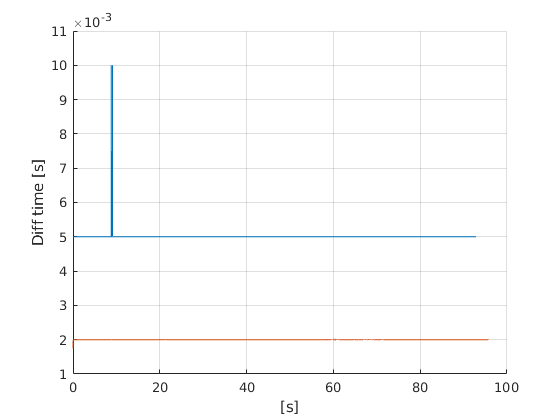

figure(); hold on
plot(t(1:end-1), diff(t), 'DisplayName',"Motion Capture")
plot(data_IMU.time(1:end-1),diff(data_IMU.time),'DisplayName',"IMU")
xlabel("[s]")
ylabel("Diff time [s]")
grid on

Some missing samples.

#### 3D plot of trajectory MC system

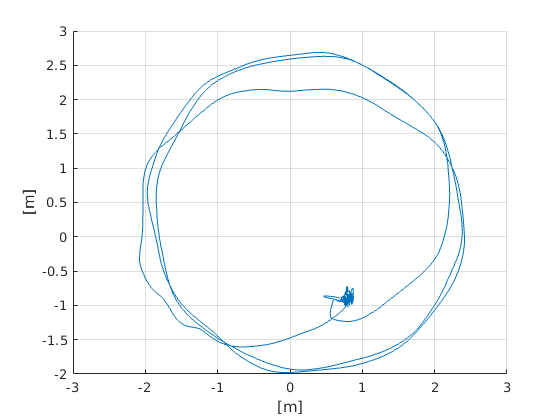

figure(); clf; hold on
plot3(p(1,:),p(2,:), p(3,:))

grid on

xlabel("[m]")
ylabel("[m]")

### Check position in regular 2D plot

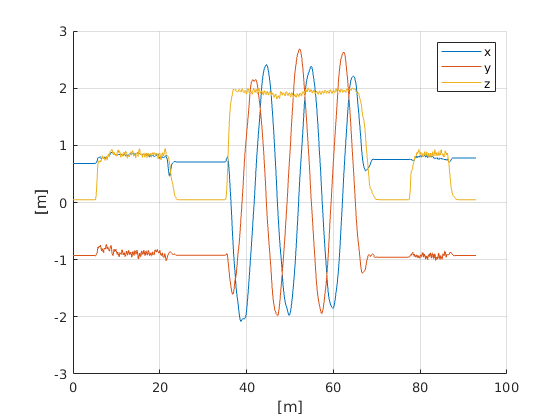

dirs = ["x","y","z"];
figure(); clf; hold on
for i =1:3
    plot(t, p(i,:),"DisplayName",dirs(i))
end

grid on
legend()
xlabel("[m]")
ylabel("[m]")

#### Rig rotation matrix

The rotation matrix is from local to global, that is body to global 

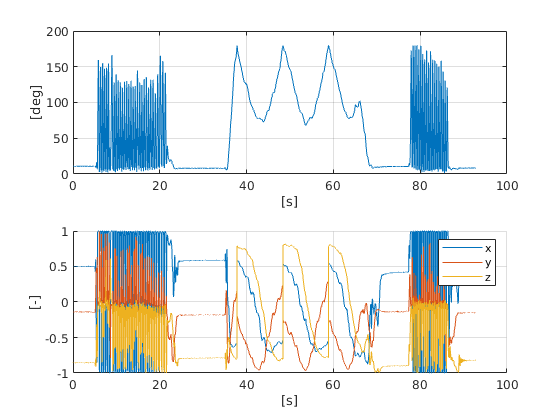

R_nb_rig_tot = squeeze(data_mc.RigidBodies.Rotations); % Rotation matrix
R_nb_rig = R_nb_rig_tot(:,good_points); % Take away nans 
R_nb_rig_3x3 = reshape(R_nb_rig,3,3,[]);
R_bn_rig_3x3 = zeros(size(R_nb_rig_3x3));

for n = 1:size(R_nb_rig_3x3,3)
    R_bn_rig_3x3(:,:,n) = R_nb_rig_3x3(:,:,n)';
end

figure(); hold on
ax = zeros(2,1);

axang = rotm2axang(R_nb_rig_3x3);
ax(1) = subplot(2,1,1);


plot(t, rad2deg(axang(:,4)))
% set(gca, "YScale", "log")
grid on
xlabel("[s]")
ylabel("[deg]")


ax(2) = subplot(2,1,2); hold on
for i = 1:3
    plot(t, axang(:,i))
end
grid on
legend("x","y","z")
xlabel("[s]")
ylabel("[-]")


% linkaxes(ax, "x");

## Estimate angular velocity from MC rotation matrices 

Use a forward differencing scheme.

w_nb_hat =  R2w_central_diff(R_nb_rig_3x3, t)

w_nb_hat =        NaN    0.0571   -0.0639   -0.0728   -0.0134    0.1213    0.1136   -0.1517   -0.0713    0.1178    0.0227   -0.0186    0.0155   -0.0291   -0.0433   -0.0187   -0.0401    0.0092    0.1360    0.0802   -0.0767   -0.0878    0.0286    0.0884   -0.0371   -0.0400    0.0317   -0.0136   -0.0434   -0.0304    0.0336    0.0235   -0.0157   -0.0403    0.0135    0.0239   -0.0114    0.0547    0.0600   -0.0245   -0.0937   -0.0590    0.0420    0.0260    0.0036    0.0309   -0.0274   -0.0142    0.0109    0.0481
       NaN    0.0133   -0.0087   -0.0036    0.0028   -0.0208   -0.0284    0.0051    0.0054   -0.0026    0.0148    0.0015   -0.0156    0.0122    0.0000   -0.0269    0.0069    0.0117   -0.0097   -0.0003    0.0062   -0.0004    0.0101    0.0077   -0.0232   -0.0052    0.0240   -0.0014   -0.0088   -0.0095   -0.0055    0.0180    0.0003   -0.0079    0.0090    0.0049    0.0036   -0.0120   -0.0111    0.0082    0.0198    0.0108   -0.0311   -0.0098    0.0163   -0.0183    0.0143    0.0055   -0.00

% Set the neighbours
w_nb_hat(:,1) = w_nb_hat(:,2);
w_nb_hat(:,end) = w_nb_hat(:,end-1);
% zeros(3,length(t));
% 
% for k = 2:length(t)
%     dt = t(k) - t(k-1);
%     w_nb_hat(:,k) = logSO3(R_nb_rig_3x3(:,:,k-1)'*R_nb_rig_3x3(:,:,k))/dt;
% end


## Rotate IMU to IMU-rig coarse

Found this matrix by looking at the photos.

### Plot angular velocity components

figure()
ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU_mc_frame.time, data_IMU_mc_frame.mean_gyro(i,:), "DisplayName","IMU")
    grid on 
    legend
end
linkaxes(ax, 'x'); clf reset;

Looks like they are the same.

### Plot angular velocity norm

Compare the norm instead, not depedent on the orientation of the rig

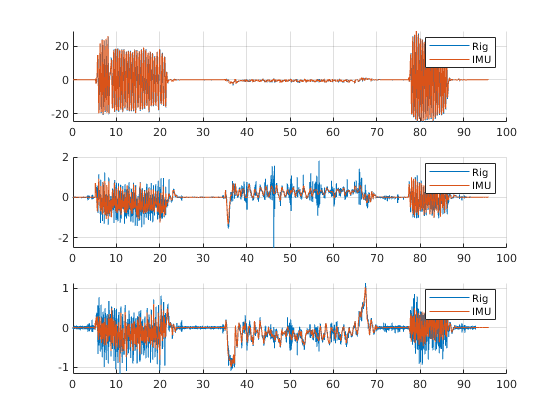

figure()

ax = zeros(3,1);
hold on
plot(t, norm_time(w_nb_hat), "DisplayName","Rig")
plot(data_IMU.time, norm_time(data_IMU_mc_frame.mean_gyro), "DisplayName","IMU")
grid on 
legend

The normed signal of the angular velocity does not look very smooth, that can be explained by the $y$ and $z$ components that are quire noisy. It is then better to just use $x$ component.

## Estimate rotation matrix between IMU and rig using gravity (Fine alignment)

The body frames of the IMU and the rig is not perfectly aligned. 

Downward in bodyframe should point in the direction of gravity in body frame coordinates.

Downward of the navigation frame is the third column of the R_bn matrix, the rotation matrix from navigation frame to body frame.

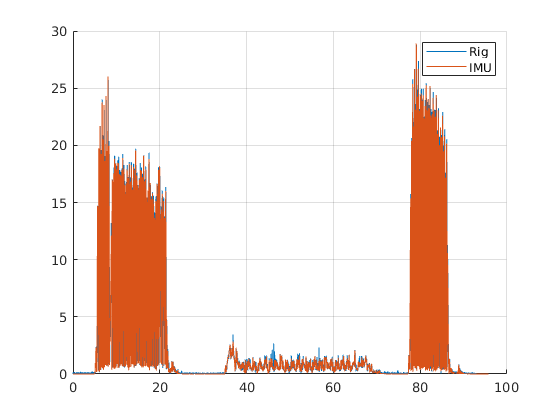

rig_unit_tot = reshape(R_bn_rig_3x3(:,3,:),3,[])
imu_unit_tot = normalize_norm_v(data_IMU_mc_frame.mean_acc)

mask_stationary_rig = t <= 0.5;
mask_stationary_IMU = data_IMU_mc_frame.time <= 4;

figure(); 

rig_unit_tot =     0.0186    0.0185    0.0185    0.0186    0.0185    0.0186    0.0187    0.0188    0.0187    0.0188    0.0187    0.0186    0.0187    0.0188    0.0186    0.0188    0.0188    0.0187    0.0187    0.0188    0.0187    0.0187    0.0187    0.0186    0.0186    0.0189    0.0187    0.0186    0.0187    0.0187    0.0188    0.0188    0.0186    0.0188    0.0187    0.0187    0.0187    0.0186    0.0188    0.0187    0.0187    0.0186    0.0186    0.0189    0.0187    0.0187    0.0189    0.0186    0.0188    0.0186
    0.0964    0.0968    0.0969    0.0962    0.0962    0.0961    0.0974    0.0972    0.0959    0.0965    0.0971    0.0967    0.0969    0.0969    0.0966    0.0964    0.0964    0.0960    0.0965    0.0974    0.0973    0.0966    0.0964    0.0969    0.0973    0.0966    0.0969    0.0969    0.0968    0.0964    0.0965    0.0968    0.0967    0.0966    0.0963    0.0968    0.0965    0.0966    0.0971    0.0972    0.0969    0.0963    0.0963    0.0967    0.0965    0.0968    0.0968    0.0965    

for i = 1:3

imu_unit_tot =     0.0036    0.0025    0.0034    0.0031    0.0028    0.0023    0.0031    0.0029    0.0045    0.0039    0.0034    0.0037    0.0033    0.0028    0.0052    0.0033    0.0037    0.0032    0.0032    0.0034    0.0036    0.0032    0.0036    0.0034    0.0031    0.0039    0.0026    0.0030    0.0025    0.0023    0.0043    0.0032    0.0028    0.0042    0.0030    0.0039    0.0030    0.0018    0.0040    0.0023    0.0041    0.0042    0.0028    0.0046    0.0036    0.0017    0.0031    0.0022    0.0032    0.0022
    0.0545    0.0543    0.0527    0.0546    0.0540    0.0536    0.0546    0.0543    0.0541    0.0539    0.0551    0.0540    0.0525    0.0527    0.0532    0.0544    0.0533    0.0533    0.0537    0.0534    0.0536    0.0540    0.0538    0.0534    0.0545    0.0535    0.0548    0.0545    0.0542    0.0530    0.0545    0.0539    0.0550    0.0541    0.0543    0.0540    0.0536    0.0534    0.0532    0.0532    0.0535    0.0535    0.0534    0.0530    0.0536    0.0540    0.0545    0.0535    

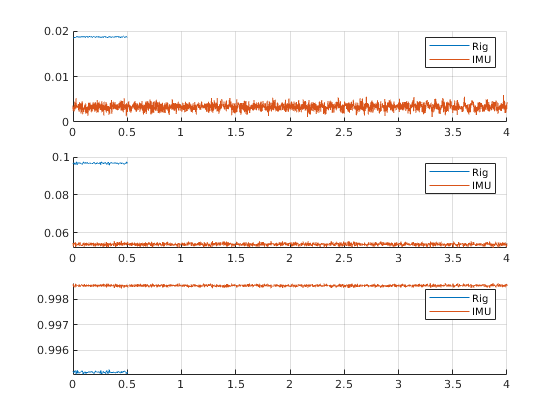

    subplot(3,1,i); hold on 
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot(i,mask_stationary_IMU), "DisplayName","IMU")
    grid on 
    legend
end

### Find angle difference 

[R_stationary_rig_mean, e_R] = average_rotation(R_bn_rig_3x3(:,:,mask_stationary_rig), 100, 1e-12)

1/100: tol: 4.654e-04 / 1.000e-12
2/100: tol: 3.829e-12 / 1.000e-12
3/100: tol: 5.822e-18 / 1.000e-12


R_stationary_rig_mean =     0.9865   -0.1624    0.0187
    0.1599    0.9824    0.0967
   -0.0341   -0.0924    0.9951


e_R =     0.0003   -0.0002   -0.0003    0.0005    0.0005    0.0006   -0.0007   -0.0005    0.0008    0.0002   -0.0004   -0.0000   -0.0002   -0.0002    0.0001    0.0003    0.0003    0.0007    0.0002   -0.0007   -0.0006    0.0001    0.0003   -0.0002   -0.0006    0.0002   -0.0002   -0.0002   -0.0001    0.0003    0.0002   -0.0001   -0.0000    0.0001    0.0004   -0.0001    0.0001    0.0001   -0.0004   -0.0005   -0.0001    0.0004    0.0004    0.0000    0.0002   -0.0001   -0.0001    0.0002    0.0000    0.0001
   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002    0.0002    0.0002   -0.0001    0.0000    0.0001   -0.0001    0.0000    0.0001   -0.0001    0.0000    0.0001   -0.0001   -0.0000    0.0002    0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0002    0.0000   -0.0000    0.0000   -0.0000    0.0001    0.0001   -0.0001    0.0001   -0.0000   -0.0000   -0.0001   -0.0001    0.0001    0.0001    0.0000   -0.0002   -0.0002    0.0002   -0.0000    0.0000    0.0002   -0.0002    0.0001   

det(R_stationary_rig_mean)

ans = 1.0000

R_stationary_rig_mean'*R_stationary_rig_mean

ans =     1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


dir_rig = R_stationary_rig_mean(:,3)

dir_rig =     0.0187
    0.0967
    0.9951


norm(dir_rig)

ans = 1.0000

dir_imu = normalize_norm_v(mean(data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU),2))

dir_imu =     0.0033
    0.0539
    0.9985



norm(dir_imu)

ans = 1

acosd(dot(dir_rig,dir_imu))

ans = 2.6138

3 degress difference. Level spirit sensitivity is 10mm/m

atand(10e-3/1)

ans = 0.5729

Which is 0.5 deg. Meaning the difference is above what the level spirit can measure. 

Rotationmatrix between unit vectors, from 

R_rig_coarse2rig_fine = rotationMatrixFromTwoUnitVectors(dir_imu, dir_rig)

R_rig_coarse2rig_fine =     0.9999    0.0004    0.0154
   -0.0010    0.9991    0.0429
   -0.0153   -0.0429    0.9990


It is almost the identiy matrix

rad2deg(my_rotm2eul(R_rig_coarse2rig_fine))

ans =    -2.4613
    0.8793
   -0.0582



det(R_rig_coarse2rig_fine)

ans = 1

R_rig_coarse2rig_fine'*R_rig_coarse2rig_fine

ans =     1.0000   -0.0000   -0.0000
   -0.0000    1.0000         0
   -0.0000         0    1.0000


R_rig_coarse2rig_fine*dir_imu

ans =     0.0187
    0.0967
    0.9951


dir_rig

dir_rig =     0.0187
    0.0967
    0.9951


norm(R_rig_coarse2rig_fine*dir_imu - dir_rig)

ans = 1.1932e-08

How many degress does the rotation matrix rotate.

rad2deg(norm(logSO3(R_rig_coarse2rig_fine)))

ans = 2.6138

Check that the rotation matrix is reasonable 

imu_unit_tot_2 = normalize_norm_v(R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU))

imu_unit_tot_2 =     0.0190    0.0178    0.0187    0.0185    0.0181    0.0177    0.0185    0.0182    0.0198    0.0193    0.0188    0.0191    0.0186    0.0182    0.0206    0.0187    0.0190    0.0186    0.0186    0.0188    0.0190    0.0185    0.0190    0.0188    0.0184    0.0193    0.0179    0.0183    0.0178    0.0176    0.0197    0.0186    0.0182    0.0196    0.0184    0.0193    0.0183    0.0172    0.0193    0.0176    0.0194    0.0196    0.0181    0.0199    0.0190    0.0171    0.0185    0.0176    0.0186    0.0176
    0.0973    0.0971    0.0955    0.0974    0.0968    0.0965    0.0974    0.0971    0.0969    0.0967    0.0979    0.0969    0.0953    0.0955    0.0960    0.0972    0.0961    0.0962    0.0965    0.0962    0.0964    0.0969    0.0966    0.0962    0.0973    0.0963    0.0976    0.0973    0.0971    0.0958    0.0973    0.0967    0.0978    0.0969    0.0972    0.0968    0.0964    0.0962    0.0960    0.0960    0.0963    0.0963    0.0962    0.0958    0.0964    0.0969    0.0973    0.0963  

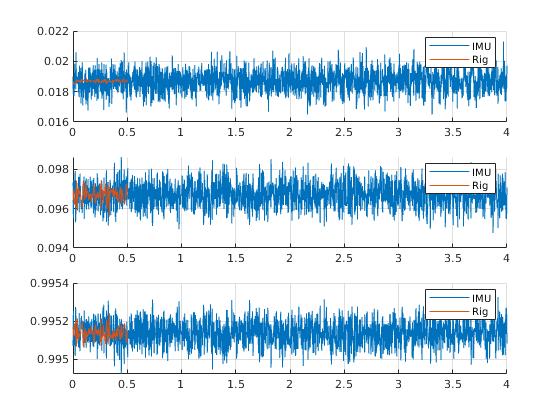

figure(); 
for i = 1:3
    subplot(3,1,i); hold on 
    
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot_2(i,mask_stationary_IMU), "DisplayName","IMU")
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    grid on 
    legend
end

Check that gyro gives reasonable reasults as well

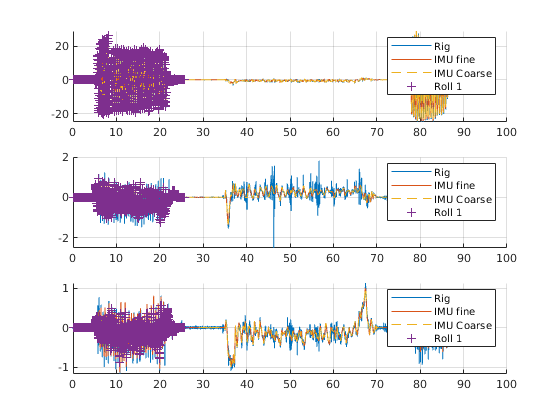

phase_roll_1 = data_IMU.start_and_stop(1,1):data_IMU.start_and_stop(2,1);
gyro_2 = R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_gyro;
figure()
ax = zeros(3,1);

for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU.time, gyro_2(i,:) , "DisplayName","IMU fine ")
    plot(data_IMU.time, data_IMU_mc_frame.mean_gyro(i,:) ,"--", "DisplayName","IMU Coarse")
    plot(data_IMU.time(phase_roll_1), data_IMU_mc_frame.mean_gyro(i,phase_roll_1) ,"+", "DisplayName","Roll 1", "MarkerIndices",1:10:length(phase_roll_1))
    grid on 
    legend
end

The fine rotation does not matter.

#### Rotatate measurements fine alignment

## Grid search time sync

Extract the phase time sync sequence

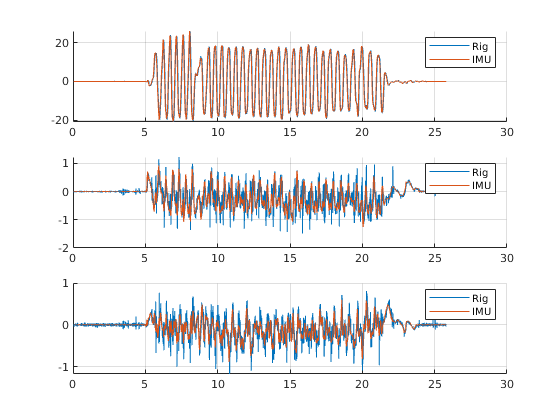


figure
ax = zeros(3,1);
time_IMU = data_IMU.time(phase_roll_1);
mask_time_rig = logical( (t >= time_IMU(1)) .* (t <= time_IMU(end)));
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t(mask_time_rig), w_nb_hat(i,mask_time_rig), "DisplayName","Rig")
    plot(time_IMU, data_IMU_mc_frame.mean_gyro(i,phase_roll_1), "DisplayName","IMU")
    grid on 
    legend
end
slice_time_sync_1_phase = phase_roll_1
% linkaxes(ax);

Interpolate rig w to IMU angular velocity. Use the x direction.

y_interp = data_IMU_mc_frame.mean_gyro(1,slice_time_sync_1_phase);

slice_time_sync_1_phase =     25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74


t_interp = time_IMU;
length(t_interp)

% cubic spline iterpolation 
f = @(t_shift) interp1( t, w_nb_hat(1,:),  t_interp - t_shift, 'pchip');
f(0)

cost = @(t_shift) sum((y_interp - f(t_shift)).^2);

ans = 12877

cost(0)

Ocular inspection of coarse time shift 

t_shift_coarse = 0.0


ans =     0.0711    0.0261    0.0026   -0.0148   -0.0166    0.0009    0.0153    0.0047   -0.0190   -0.0323   -0.0396   -0.0432   -0.0364   -0.0226   -0.0200   -0.0310   -0.0399   -0.0319   -0.0086    0.0244    0.0898    0.1352    0.1269    0.1006    0.0623   -0.0161   -0.0747   -0.0828   -0.0870   -0.0823   -0.0319    0.0240    0.0570    0.0827    0.0810    0.0172   -0.0359   -0.0388   -0.0398   -0.0357    0.0011    0.0311    0.0218   -0.0014   -0.0192   -0.0347   -0.0433   -0.0415   -0.0355   -0.0243


grid_search = t_shift_coarse + (-0.3:0.01:0.3);
cost_grid = arrayfun(cost, grid_search);


ans = 1.8027e+05

options = optimset('Display','iter','TolX', 1e-12);
t_shift_opt = fminbnd(cost,grid_search(1),grid_search(end),options);


t_shift_coarse = 0

data_IMU.time_shifted = data_IMU.time - t_shift_opt;
figure(); clf;
plot(grid_search, cost_grid, "-x")
hold on 
yLim = ylim;
plot(t_shift_opt*ones(1,2), yLim, "-r")

 
 Func-count     x          f(x)         Procedure
    1     -0.0708204       469779        initial
    2      0.0708204  1.92782e+06        golden
    3      -0.158359  3.03405e+06        golden
    4     -0.0297973      2713.41        parabolic
    5      -0.023888      2544.51        parabolic
    6     -0.0267836      387.359        parabolic
    7      -0.026787      387.356        parabolic
    8     -0.0267869      387.356        parabolic
    9     -0.0267869      387.356        parabolic
   10     -0.0267869      387.356        parabolic
   11     -0.0267869      387.356        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-12 



ylim(yLim);

### Ensure time shift is ok

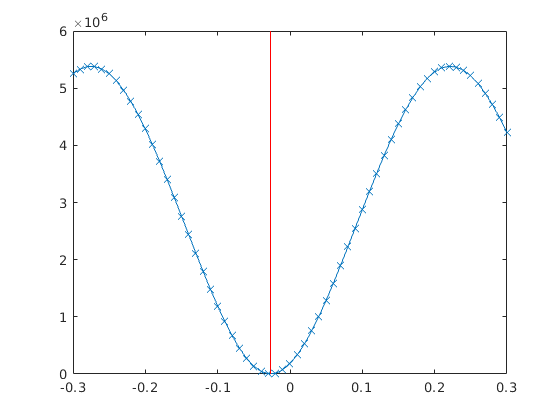

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;
    plot(t, rad2deg(w_nb_hat(i,:))', 'DisplayName', "MC")


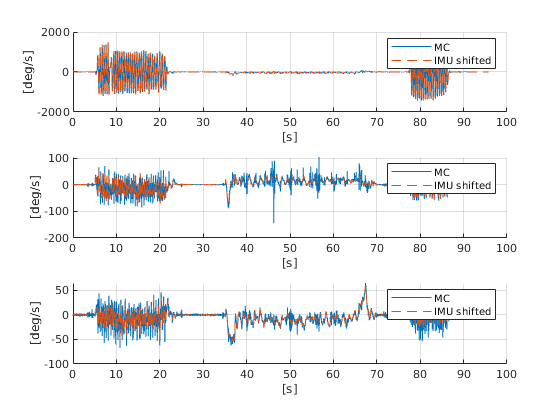

    % plot(data_IMU.time, rad2deg(data_IMU_gyro.gyro_wls_wo_bias_rig_frame_fine(i,:)),'DisplayName','IMU')
    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"--",'DisplayName','IMU shifted')
    
    % yLim = ylim; 
    % X = [data_IMU.start_and_stop(1,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(1,1)];
    % Y = [yLim(2) yLim(2) yLim(1) yLim(1)];
    % fill(data_IMU.time_stamp_corr(X), Y, "b", "FaceAlpha", 0.2);
    % ylim(yLim);
    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
end

figure(); hold on 
plot(data_IMU.time_shifted, "DisplayName","Shifted time")
plot(data_IMU.time, "DisplayName","Original Time")
plot(t, "DisplayName","Rig Time")
legend
grid on 


xlim([0 391])
ylim([-1.35 0.71])

## Find release times

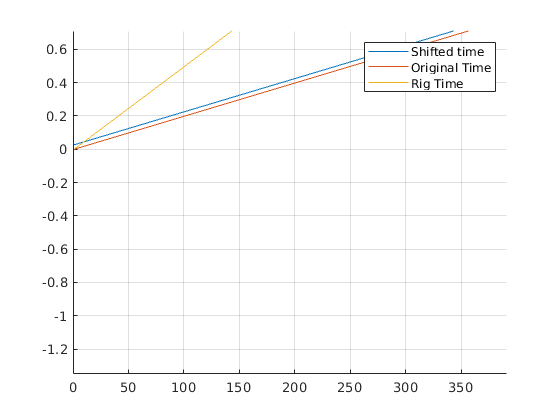



release_times_roll_2 = 77.5 + (0:19)*0.2
release_times_roll_2_end = release_times_roll_2 + 5;

w_roll_2_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2)';
w_roll_2_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2_end)';



release_times_middle = 35 + (0:19)*1.6
release_times_middle_end = release_times_middle + 5;

w_middle_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle)';

release_times_roll_2 =    77.5000   77.7000   77.9000   78.1000   78.3000   78.5000   78.7000   78.9000   79.1000   79.3000   79.5000   79.7000   79.9000   80.1000   80.3000   80.5000   80.7000   80.9000   81.1000   81.3000


w_middle_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle_end)';

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;

release_times_middle =    35.0000   36.6000   38.2000   39.8000   41.4000   43.0000   44.6000   46.2000   47.8000   49.4000   51.0000   52.6000   54.2000   55.8000   57.4000   59.0000   60.6000   62.2000   63.8000   65.4000


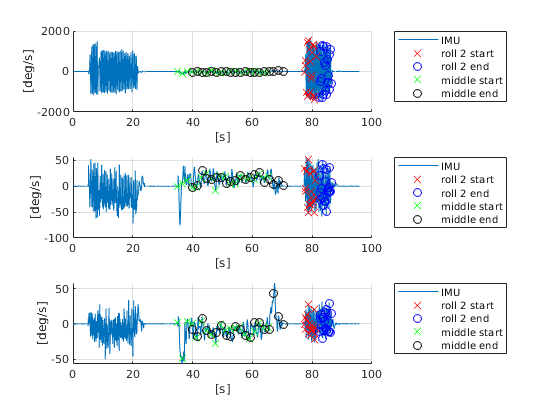


    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"-",'DisplayName','IMU')
    plot(release_times_roll_2, rad2deg(w_roll_2_start(i,:)),"rx",'DisplayName','roll 2 start')
    plot(release_times_roll_2_end, rad2deg(w_roll_2_end(i,:)),"bo",'DisplayName','roll 2 end')
    
    plot(release_times_middle, rad2deg(w_middle_start(i,:)),"gx",'DisplayName','middle start')
    plot(release_times_middle_end, rad2deg(w_middle_end(i,:)),"ko",'DisplayName','middle end')

    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
    legend("Location","bestoutside")
end

## Save Joint data

mkdir(fullfile(pathScript,"estimated_parameters"))

% save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt");
save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt", "release_times_middle", "release_times_roll_2");
% save(fullfile(pathScript,"data_processed","data_initial_values.mat"),"-struct", "data_initial_values");

## Conclusions 

- Coarse alignment is only off by 3 degrees.

- The time-sync was performed on the fine aligned gyroscope wls data, but it is expected that this does not matter if the time-shift estimation was done on the coarse aligned data.

- The time-shift was estimation was done using linearly interpolated data and grid-search. 